# Assignment 5 - Doppler shift

## Background

### Doppler effect

The **Doppler effect** or **Doppler shift** is the change in frequency of a wave in relation to an observer who is moving relative to the wave source. 

A common example of Doppler shift is the change of pitch heard when a vehicle sounding a horn approaches and recedes from an observer. Compared to the emitted frequency, the received frequency is higher during the approach, identical at the instant of passing by, and lower during the recession.

In this assignment, we aim at setting up a model to study the Doppler effect.

## Model

In the computer labs, we have solved the 1D wave equation


$$u_{\textrm{tt}} -c^2 u_{\textrm{xx}} =0$$


with an initial value $u(x,0)=f_0(x)$ and $u_x(x,0)=0$.

Now, we want to consider the problem in which the initial value is zero, but the system is driven by a point source oscilating at the angular frequency $\omega$. This corresponds to the case of, for example, sound waves emitting from a loudspeaker.

The wave equation, with the source term, is now given by

$u_{\textrm{tt}} -c^2 u_{\textrm{xx}} =f$,

in which $f(x,t)$is a function of both space and time.

### Geometry

Our problem is in 1D, in order to use MATLAB PDE toolbox, we need to set up our problem accordingly.

Same as in our computer lab, we define our geometry to be a strip with width $w=0.03$. But now our domain is from $x=-L$ to $x=L$ with $L=2$.

**Note that we have set the maximum width of the trianglular mesh to be **$Hmax=0.02$**.**

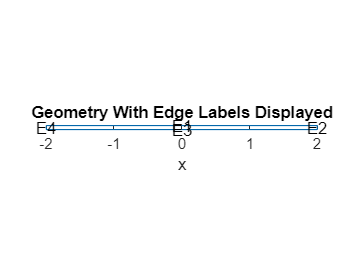

numberOfPDE = 1;
model = createpde(numberOfPDE);

w = 0.03;
L = 2;
R1 = [3,4,-L,L,L,-L,w,w,-w,-w]'; % 3 - Rectangle 4 - four vertices
gm = [R1];
sf = 'R1';
ns = char('R1');
ns = ns';

g = decsg(gm,sf,ns); % geometry

geometryFromEdges(model,g);
pdegplot(model,'EdgeLabels','on'); % plot geometry only
title 'Geometry With Edge Labels Displayed';
xlabel x
ylabel y

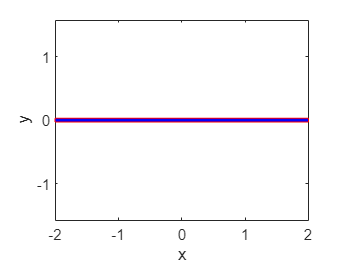


generateMesh(model, 'Hmax', 0.02); % generate mesh for the geometry
figure
pdemesh(model);
xlabel x
ylabel y

### PDE and source term

Now we need to specify the PDE and the boundary condition. **For simplicity we let **$c=1$. 

Recall that MATLAB solves a PDE in the form of

$m \frac{\partial^2 u} {\partial t^2} + d \frac{\partial u} {\partial t} - \nabla \cdot ( c \nabla u) + au = f$.

We take the source to be a gaussian function centered at $x=0$.


$$f\left(x,t\right)=e^{-{\left(\frac{x}{\Delta \;x}\right)}^2 } \cos \left(\omega t\right)\;$$


and set $d=0$, $m=1$, $c=1$, $a=0$, the equation is reduced to $u_{tt}-\Delta u=f$

**Ideally this should be a point source with no width. However, our PDE solver needs a smooth function as input. Here we set **$\Delta x = 0.02$** and **$\omega = 2\pi\times 4$**.**

c = 1;
a = 0;
m = 1;

Deltax = 0.02;
omega = 2 * pi * 4;
% we define the function x to put into the right hand side
f = @(location, state) exp(-(location.x - 0.2 * state.time).^2/(Deltax)^2) .* cos(omega * state.time);


% we put f as the function we have just defined instead of 0
specifyCoefficients(model,'m',m,'d',0,'c',c,'a',a,'f',f);

### Initial and Boundary condition.

The initial conditions are $u(0,t)=u_x(0,t)=0$

We set the boundary condition on the left and right boundary to be Dirichlet $u(\pm L,t)=0$. However we only run the simulation up to the point when the waves reach the boundaries so there will not be any reflection from the boundary.

Again, we set the Neumann boundary condition $u_y=0$ for both boundaries of $y$ so $u_y$ remains 0 (since we want to reduce it to a 1D problem).

setInitialConditions(model,0,0); % model, u(0, x) u_t(0, x)

% applyBoundaryCondition(model,"dirichlet",RegionType,RegionID,Name,Value)
%
% RegionType - Face for 3D; Edge for 2D
% RegionID - EdgeLabel for 2D, [2,4] left & right - see pdegplot
%       E1
%   E4      E2
%       E3
% Name - 
%   r — Dirichlet condition h*u = r
%   h — Dirichlet condition h*u = r
%   g — Generalized Neumann condition n·(c×∇u) + qu = g
%   q — Generalized Neumann condition n·(c×∇u) + qu = g
%   u — Dirichlet conditions

applyBoundaryCondition(model,'dirichlet','Edge',[2,4],'u',0);
applyBoundaryCondition(model,'neumann','Edge',[1,3],'g',0);

### Solving the system

Now we solve the system for 2 seconds and get the solution of $u(x,t)$ on a grid of $x$ at $y=0$.

grid_per_second = 256;
total_time = 2;
n = grid_per_second * total_time + 1;
tlist = linspace(0,total_time,n);

result = solvepde(model,tlist);

% set up the x grid we are interested in
xx = linspace(-L, L, 401);
% set up the y grid we are interested in
yy = zeros(size(xx));
% obtain u as a 2D array of space grid points and time
uintrp = interpolateSolution(result,xx,yy,1:length(tlist));

% the maximum minmum of uintrp for plotting purpose
umax = max(max(uintrp));
umin = min(min(uintrp));

If you copy the following code into the command you will be able to see an animation of $u$

clear M

figure

for i = 1:n

    plot(xx,real(uintrp(:,i)),'b');

    axis([-L L umin umax]); 

    xlabel x

    ylabel u

    M(i) = getframe;

end

Suppose Observer A is standing at $x=1$and Observer B is standing at $x=-1$.

Use interpolateSolution to obtain the wave amplitute measured by Observer A as a function of time, i.e. $u(1,t)$. Do the same for Observer B, i.e. $u(-1,t)$. 

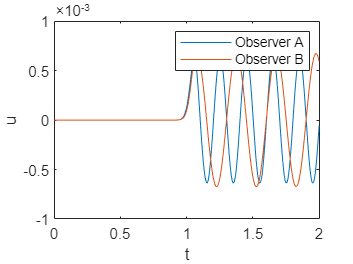

uA = interpolateSolution(result,[1],[0],1:length(tlist));
uB = interpolateSolution(result,[-1],[0],1:length(tlist));
figure
plot(tlist,uA, tlist,uB);
xlabel t
ylabel u
legend('Observer A', 'Observer B')

One can choose to use FFT to determine the frequency of the signal. However, this is not very accurate for our purpose since the frequency we are measuring is quite low. Alternatively, since we have almost a single frequency wave, we can count the time interval $t_1$ between the first peak and the last peak shortly after the signal is observed. Since each peroid will have only one peak, the peroid and frequency are simply given by

$T\;=\frac{t_1 }{\textrm{Number}\;\textrm{of}\;\textrm{peaks}},\;\textrm{freq}=\frac{1}{T}$.

You would expect to see the output being something close to 4. This is the frequency of the source.

% this is the index for start counting, just when the wave reaches the
% observer
istart = grid_per_second + 1;

% we find the peaks and their index until the end of the signal
% pks gives an array of peak amplitude and locs gives their indexs
[pks,locs] = findpeaks(uA(istart:end));

% we find the indices of the first and last peak and turn it into time
t1 = (locs(end) - locs(1)) / grid_per_second;

% compute the frequency for observer A
freqA = (numel(pks)-1) / t1;

istart = grid_per_second + 1;

[pks,locs] = findpeaks(uB(istart:end));

t1 = (locs(end) - locs(1)) / grid_per_second;

freqB = (numel(pks)-1) / t1;

freqA

freqA = 5.0443

freqB

freqB = 3.3391

Now we consider a source moving rightward at the speed $v$.


$$f\left(x,t\right)=e^{-{\left(\frac{x-v\;t}{\Delta \;x}\right)}^2 } \cos \left(\omega t\right)\;$$


Solve the equation for $v=0.5$. Plot u as a function of t at the location of Observer A and B.

What frequency do you get for Observer A and Observer B?

v = 0.5;
fp = @(location, state) exp(-(location.x - v * state.time).^2/(Deltax)^2) .* cos(omega * state.time);

specifyCoefficients(model,'m',m,'d',0,'c',c,'a',a,'f',fp);

result = solvepde(model,tlist);
uintrp = interpolateSolution(result,xx,yy,1:length(tlist));

umax = max(max(uintrp));
umin = min(min(uintrp));

uA = interpolateSolution(result,[1],[0],1:length(tlist));
uB = interpolateSolution(result,[-1],[0],1:length(tlist));
figure

hold on
plot(tlist,uA, tlist,uB);
xlabel t
ylabel u

grid

xlim([0.00 2.00])
ylim([-0.00100 0.00100])

last = min(floor(grid_per_second * 1 / v), length(tlist))

last = 512

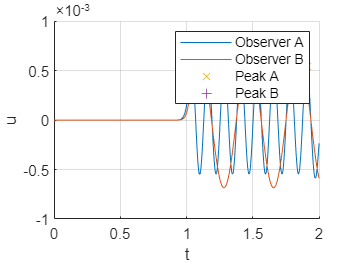


[pks,locs] = findpeaks(uA(istart:last), 'MinPeakHeight', 1e-5);
plot(tlist(locs + istart), pks, 'x') 

t1 = (locs(end) - locs(1)) / grid_per_second;

freqA = (numel(pks) - 1) / t1;

[pks,locs] = findpeaks(uB(istart:end), 'MinPeakHeight', 1e-5);

plot(tlist(locs + istart), pks, '+') 

legend('Observer A', 'Observer B', 'Peak A', 'Peak B')

hold off


t1 = (locs(end) - locs(1)) / grid_per_second;

freqB = (numel(pks) - 1) / t1;

disp(freqA);

    8.0721



disp(freqB);

    2.6667




disp(omega / (2 * pi) * c / (c - v)); % theoretic

     8



disp(omega / (2 * pi) * c / (c + v));

    2.6667



In theory, the observed frequency is given by


$$\textrm{freq}=\textrm{freq}\;\textrm{of}\;\textrm{source}\times \;\frac{c}{c\pm v}$$


in which Observer A takes the minus sign and B takes the plus sign. 

Run your code for a range of $v$ and demonstrate the result in two well labeled plots with comparison to the theoratical result.

How well does your numerical result match the theory?

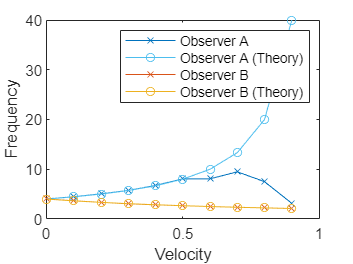

  Columns 1 through 2

    0.0052    0.0061

  Columns 3 through 4

    0.0089    0.0045

  Columns 5 through 6

    0.0105    0.0090

  Columns 7 through 8

    0.1928    0.2889

  Columns 9 through 10

    0.6254    0.9216

  Columns 1 through 2

    0.0052    0.0057

  Columns 3 through 4

    0.0017    0.0095

  Columns 5 through 6

    0.0044         0

  Columns 7 through 8

    0.0010    0.0018

  Columns 9 through 10

    0.0017    0.0033



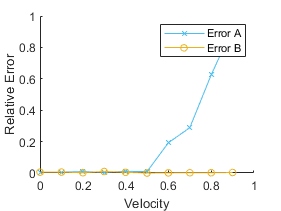

vlist = [0, 0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8, 0.9];

fA = zeros(length(vlist), 1);
fB = zeros(length(vlist), 1);

fA_theory = zeros(length(vlist), 1);
fB_theory = zeros(length(vlist), 1);

for i = 1:length(vlist)
    v = vlist(i);

    fA_theory(i) = omega / (2 * pi) * c / (c - v);
    fB_theory(i) = omega / (2 * pi) * c / (c + v);

    fq = @(location, state) exp(-(location.x - v * state.time).^2/(Deltax)^2) .* cos(omega * state.time);
    
    specifyCoefficients(model,'m',m,'d',0,'c',c,'a',a,'f',fq);
    
    result = solvepde(model,tlist);
    uintrp = interpolateSolution(result,xx,yy,1:length(tlist));
    
    umax = max(max(uintrp));
    umin = min(min(uintrp));
    
    uA = interpolateSolution(result,[1],[0],1:length(tlist));
    uB = interpolateSolution(result,[-1],[0],1:length(tlist));
    
    [pks,locs] = findpeaks(uA(istart:end));
    t1 = (locs(end) - locs(1)) / grid_per_second;
    
    fA(i) = (numel(pks) - 1) / t1;
    
    [pks,locs] = findpeaks(uB(istart:end));
    t1 = (locs(end) - locs(1)) / grid_per_second;
    
    fB(i) = (numel(pks) - 1) / t1;
end

draw_graph(fA, fA_theory, fB, fB_theory, vlist)

Does our current code also work for $v=0.6$?  If not, identify the possible cause (explain in words).

Modify your code to let it match again. After the problem is fixed, add three data points to your plot for v=0.6, 0.7, 0.8

*Hint: look at the wave plot of Observer A and B and think about why there is a sudden change.*

**Answer:**

No, it doesn't work for $v>0.5$. In our model, Observer A (whom the source is moving **towards**) is placed at $x=1$and the wave velocity $c=1$, hence as we can see in the plot in (1), from $t=1$, Observer A got to observe the wave. 

Besides this, our plot time range is $[0,2]$, if $v>0.5$, at time $t_0=\frac{1}{v}<2
$, the source reaches Observer A, and then move **away** from him (same as Observe B), which causes a sudden change 

from $t_0$.

To resolve this, we can follow some of the following instructions

- place Observer A further, say $x=0.9\times2=1.8$ 

- increase count of sampling points (decrease step of time list)

- to calculate periods more accurately, set a proper threashold for `findpeak`.

- to record more periods, extend the simulation region.

- calculate the last time point before the source passes Observer A and only count peaks before this time point

then our model will work on $v\in[0.5, 0.9]$ theoretically (without considering mesh)

here we adopt the last instruction

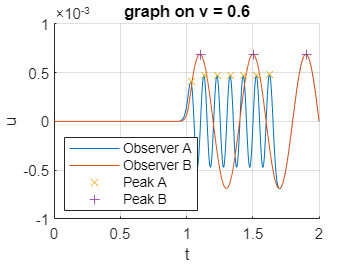

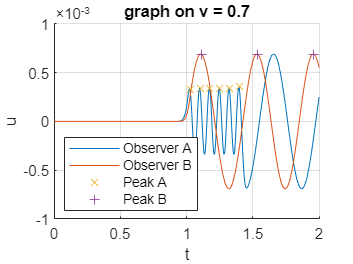

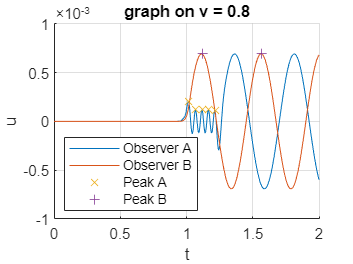

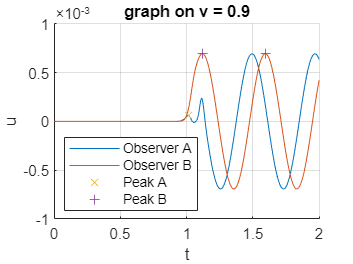

for i = 7:length(vlist)
    v = vlist(i);

    fA_theory(i) = omega / (2 * pi) * c / (c - v); % theoretic
    fB_theory(i) = omega / (2 * pi) * c / (c + v);

    fq = @(location, state) exp(-(location.x - v * state.time).^2/(Deltax)^2) .* cos(omega * state.time);
    
    specifyCoefficients(model,'m',m,'d',0,'c',c,'a',a,'f',fq);
    
    result = solvepde(model,tlist);
    uintrp = interpolateSolution(result,xx,yy,1:length(tlist));
    
    umax = max(max(uintrp));
    umin = min(min(uintrp));

    % find peaks

    uA = interpolateSolution(result,[1],[0],1:length(tlist));  % modified here
    
    last = min(floor(grid_per_second * 1 / v), length(tlist));

    [pks_A,locs_A] = findpeaks(uA(istart:last), 'MinPeakHeight', 1e-5);
    t1 = (locs_A(end) - locs_A(1)) / grid_per_second;

    fA(i) = (numel(pks_A) - 1) / t1;

    uB = interpolateSolution(result,[-1],[0],1:length(tlist)); % modified here
    
    [pks_B,locs_B] = findpeaks(uB(istart:end), 'MinPeakHeight', 1e-5);
    t1 = (locs_B(end) - locs_B(1)) / grid_per_second;
    
    fB(i) = (numel(pks_B) - 1) / t1;

    % draw observer graph
    draw_observe(uA, uB, tlist, tlist(locs_A + istart), pks_A, tlist(locs_B + istart), pks_B, "graph on v = " + v)
end

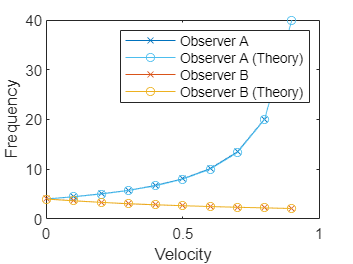

  Columns 1 through 2

    0.0052    0.0061

  Columns 3 through 4

    0.0089    0.0045

  Columns 5 through 6

    0.0105    0.0090

  Columns 7 through 8

    0.0105    0.0105

  Columns 9 through 10

    0.0039       NaN

  Columns 1 through 2

    0.0052    0.0057

  Columns 3 through 4

    0.0017    0.0095

  Columns 5 through 6

    0.0044         0

  Columns 7 through 8

    0.0010    0.0018

  Columns 9 through 10

    0.0017    0.0033



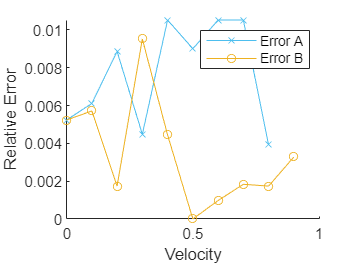


% draw error graph
draw_graph(fA, fA_theory, fB, fB_theory, vlist)

Does our current model also work for $v=0.87$? Does it match the theory? 

If not, identify the possible causes and suggest how to fix it (you don't need to actually do it, although you might be more confident with your answer if you succeed).

*Hint: read the text in this live script again. You can also try to compute the wave length*

***Answer:***

for $v=0.87$, the frequency of the wave observed by Observer A should be $f=4\times\frac{1}{1-0.13}\approx30.77$, hence the wave length is $\lambda = \frac{v}{f} \approx0.028$, and the length between trough and peak is approximately $0.014$.

Note that the target maximum element edge length of the mesh we created at the beginning is $0.02>0.14$, it will be hard to capture peaks when solving after discretization. 

Thus a bad simulation result will possibly be output, from which we can hardly see the amplitude and stable period of the first (A) wave curve, as is shown in the last cell.

**Additional Functions:**

function draw_graph(fA, fA_theory, fB, fB_theory, velocities)
    point_size = 5;

    % results
    figure
    plot(velocities, fA', 'rx-', 'MarkerEdgeColor', '#0072BD', 'color', '#0072BD', 'MarkerSize', point_size)
    hold on
    plot(velocities, fA_theory', 'ro-', 'MarkerEdgeColor', '#4DBEEE', 'color', '#4DBEEE', 'MarkerSize', point_size)
    plot(velocities, fB', 'rx-', 'MarkerEdgeColor', '#D95319', 'color', '#D95319', 'MarkerSize', point_size)
    plot(velocities, fB_theory', 'ro-','MarkerEdgeColor', '#EDB120', 'color', '#EDB120', 'MarkerSize', point_size)
    legend(["Observer A", "Observer A (Theory)", "Observer B", "Observer B (Theory)"])
    xlabel("Velocity")
    ylabel("Frequency")
    hold off
    
    
    % relative errors
    figure
    err = @(sim, theory) abs(sim - theory) ./ theory;
    errA = err(fA, fA_theory)';
    errB = err(fB, fB_theory)';
    disp(errA);
    disp(errB);
    hold on
    plot(velocities, errA, 'rx-', 'MarkerEdgeColor', '#4DBEEE', 'color', '#4DBEEE', 'MarkerSize', point_size)
    plot(velocities, errB, 'ro-','MarkerEdgeColor', '#EDB120', 'color', '#EDB120', 'MarkerSize', point_size)
    legend(["Error A", "Error B"])
    xlabel("Velocity")
    ylabel("Relative Error")
    hold off
end

function draw_observe(u1, u2, tlist, pkts1, pks1, pkts2, pks2, ttl)
    % draw simulation result
    figure

    hold on
    plot(tlist, u1, tlist, u2);
    xlabel t
    ylabel u
    title(ttl)
    
    grid
    
    xlim([0.00 2.00])
    ylim([-0.00100 0.00100])

    plot(pkts1, pks1, 'x') 
    plot(pkts2, pks2, '+') 
    
    legend('Observer A', 'Observer B', 'Peak A', 'Peak B', 'Location', 'SouthWest')
    hold off
end